clear 
close all 
clc


Run Progarm

 
note = "/dev/cu.usbmodem1101";
device = serialport(note,9600);

Selecting Mode of Operation:

mode = "Auto"; clean_data = true;
maxdata =20;numReadings = 10;

Auto Mode Control:

min_step = 5;min_scan = 1;
min_angle = 45; max_angle = 125;
max_val = max_angle-5;step_size = max_angle - min_angle+6; dist= max_angle - min_angle;
time_delay = 0.5;

Manual Mode Control:

manual_pos = 100;manual_delay = 0.5;

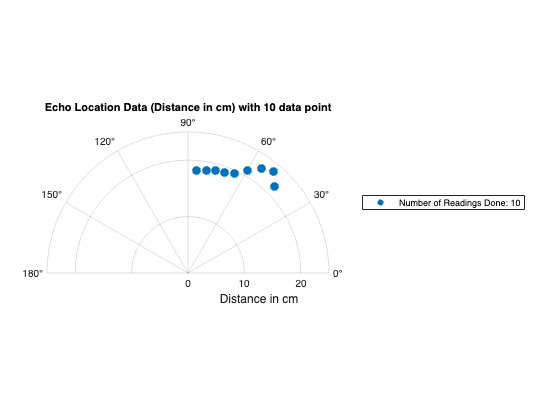

distancePattern = 'Distance in cm:\s*([\d.]+)';
anglePattern = 'at angle:\s*(\d+)';
csvFileName = 'data.csv';

% Creating new data
times = datetime.empty(maxdata, 0);
rho = zeros(maxdata, 1);
angle = zeros(maxdata, 1);

oldmax_data = 0;

% Restoring old data
if clean_data == 0
    data = readtable(csvFileName);
    oldmax_data = height(data);
    
    if maxdata >= oldmax_data
        times(1:oldmax_data) = data.Times;
        rho(1:oldmax_data) = data.Distance;
        angle(1:oldmax_data) = data.Angle;
    else
        times(1:maxdata) = data.Times(1:maxdata);
        rho(1:maxdata) = data.Distance(1:maxdata);
        angle(1:maxdata) = data.Angle(1:maxdata);
    end
end

if clean_data == 1
    oldmax_data = 0;
end

% Writing variables
pause(2);
write(device, mode, "String");

pause(1);
if mode == "Auto"
    % You can simplify this section using a loop
    settings = ["Increment", "Move Delay", "Min Angle", "Max Angle", "Pulse Number"];
    values = [min_step, time_delay, min_angle, max_angle, min_scan];
    
    for i = 1:length(settings)
        write(device, strcat(settings(i), " = ", num2str(values(i))), "string");
        pause(0.01);
    end
end

if mode == "Manual"
    write(device, strcat("Manual Angle  = ", num2str(manual_pos)), "string");
    pause(0.01);
    write(device, strcat("Pulse Rate = ", num2str(manual_delay)), "string");
    pause(0.01);
end

num_step = 1;
sz = 75;
for i = oldmax_data:(numReadings + oldmax_data-1)
    text = readline(device);
    
    distanceMatches = regexp(text, distancePattern, 'tokens', 'once');
    angleMatches = regexp(text, anglePattern, 'tokens', 'once');

    % Store data
    index = rem(i, maxdata) + 1;
    times(index) = datetime("now");
    rho(index) = str2double(distanceMatches{1});
    angle(index) = deg2rad(str2double(angleMatches{1}));
    
    % Store data into a CSV file if we have a complete set
    if ((i > 1) && (rem(i, maxdata) == 0)) || (i >= maxdata)
        data = table(times', rho, angle, 'VariableNames', {'Times', 'Distance', 'Angle'});
        sortedData = sortrows(data, 'Times', 'descend');
        writetable(sortedData, csvFileName);
    end
    
    % Update the polar scatter plot
    polarscatter(angle(1:min(i, maxdata)), rho(1:min(i, maxdata)),sz,'filled');
    pax = gca;  % Get the current polar axes
    pax.ThetaLim = [0, 180];
    rule = pax.RAxis;
    rlabel = rule.Label;
    rlabel.String = 'Distance in cm';
    t1 = sprintf('Echo Location Data (Distance in cm) with %.0f data point', min(i+1,maxdata));
    title(t1);   
    numstr = sprintf('Number of Readings Done: %.0f', num_step);
    legend(numstr);
    num_step = num_step + 1;
    pause(0.0001);
end


pause(1);
write(device, "Off", "string");

data = table(times', rho, angle, 'VariableNames', {'Times', 'Distance', 'Angle'});
sortedData = sortrows(data, 'Times', 'descend');
writetable(sortedData, csvFileName);



